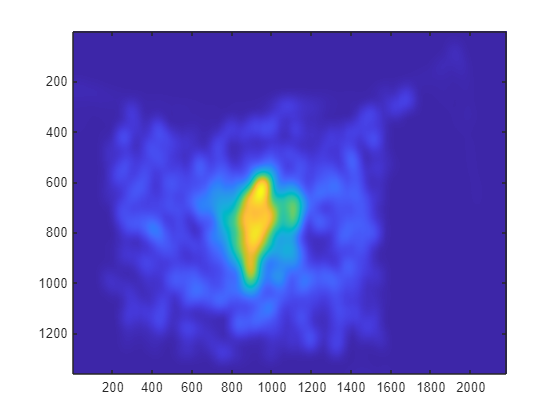

%creating the heatmap of unit firing locations, based on the eye-tracking coordinates

spike_ts_unix = neural.Timestamps(1000);

spike_ts_unix_ms = int64(round(spike_ts{1}*1000));

posX = int64(eye_track.Samples.posX);
posY = int64(eye_track.Samples.posY);

eye_track_ts_unix_ms = eye_track.Samples.eye_track_timeline_unix_ms;

firing_map = zeros(max(posX),max(posY));

for i = 1:numel(spike_ts_unix_ms)

    curr_spike_ind = find(eye_track_ts_unix_ms==spike_ts_unix_ms(i));

    curr_spike_posX = posX(curr_spike_ind);
    curr_spike_posY = posY(curr_spike_ind);

    if curr_spike_posX > 0 & curr_spike_posY > 0

    firing_map(curr_spike_posX,curr_spike_posY) = firing_map(curr_spike_posX,curr_spike_posY) + 1;

    end
end


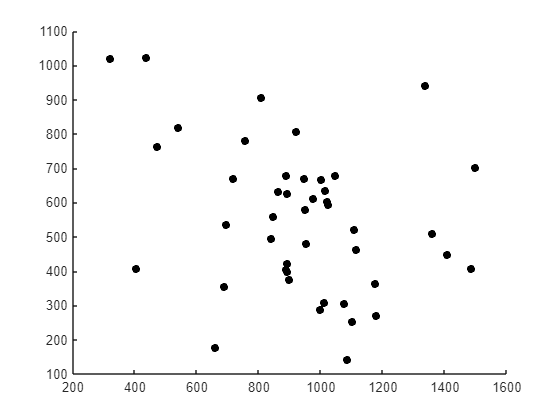

%create another map, that shows occupancy (time spent in each spatial bin).
%both maps should be smoothed using the same smoothing parameters

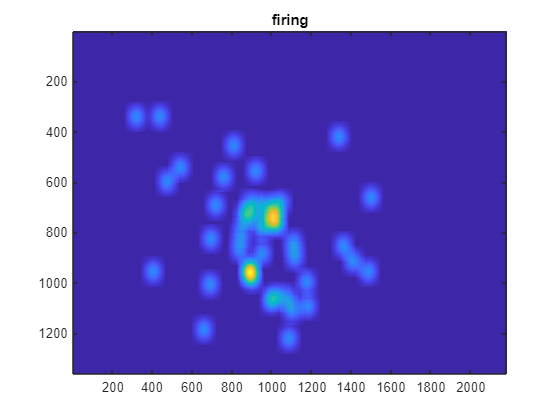

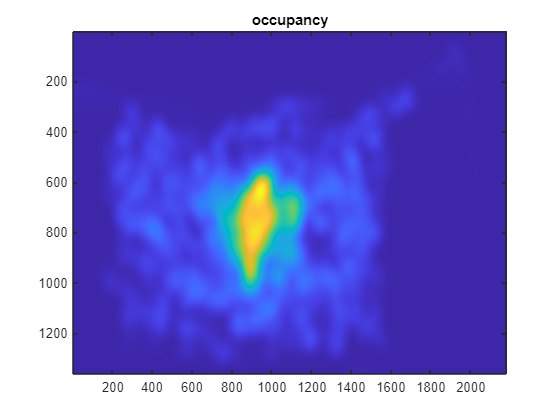


occupancy_map = zeros(max(posX),max(posY));

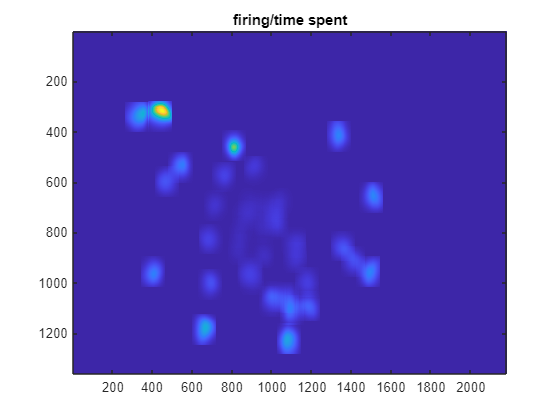

for i = 1:numel(posX)



    if posX(i) > 0 & posY(i) > 0

    occupancy_map(posX(i),posY(i)) = occupancy_map(curr_spike_posX,curr_spike_posY) + 1;

    end
end

occupancy_map_smooth = imgaussfilt(occupancy_map,30);
figure;imagesc(rot90(occupancy_map_smooth)); 

spatial_firing_map_smooth = firing_map_smooth./occupancy_map_smooth;

figure;hold on;

for i = 1:numel(spike_ts_unix_ms)

    curr_spike_ind = find(eye_track_ts_unix_ms==spike_ts_unix_ms(i));
    curr_spike_posX = posX(curr_spike_ind);
    curr_spike_posY = posY(curr_spike_ind);

    if curr_spike_posX > 0 & curr_spike_posY > 0

    scatter(curr_spike_posX,curr_spike_posY,'ko','filled');

    end
end

figure;imagesc(rot90(firing_map_smooth));title('firing')
figure;imagesc(rot90(occupancy_map_smooth));title('occupancy')
figure;imagesc(rot90(spatial_firing_map_smooth));title('firing/time spent')